point_w = [0, 0, 0.4]';
point_w_hom = [point_w; 1]

point_w_hom =          0
         0
    0.4000
    1.0000



quat_link_world = quaternion(0.70711, 0, 0.70711, 0);
orient_link= rotmat(quat_link_world,'frame');
R_w2link = orient_link

R_w2link =     0.0000         0   -1.0000
         0    1.0000         0
    1.0000         0    0.0000


T_link = [0 0 1]';


R_link2cam = [0 0 1;
             -1 0 0;
              0 -1 0]';
Proj_w2link = [R_w2link, -R_w2link*T_link; 0,0,0,1]

Proj_w2link =     0.0000         0   -1.0000    1.0000
         0    1.0000         0         0
    1.0000         0    0.0000   -0.0000
         0         0         0    1.0000


point_link_hom =     0.6000
         0
   -0.0000
    1.0000


Proj_link2Cam =      0    -1     0     0
     0     0    -1     0
     1     0     0     0
     0     0     0     1


Proj_link2Cam = [R_link2cam, zeros(3,1);
                zeros(1,3), 1]

point_cam_hom =          0
    0.0000
    0.6000
    1.0000


Proj_w2cam = Proj_link2Cam * Proj_w2link;

point_cam_hom = Proj_link2Cam * point_link_hom
point_cam = point_cam_hom(1:3);
point_link_hom = Proj_w2link * point_w_hom
point_link = point_link_hom(1:3);
point_cam_hom2 = Proj_w2cam * point_w_hom

point_cam_hom2 =          0
    0.0000
    0.6000
    1.0000


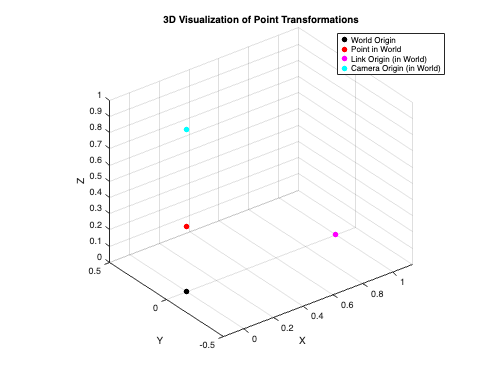

% 시각화
figure;
hold on;

% 원점 (월드 좌표계)
scatter3(0, 0, 0, 'k', 'filled', 'DisplayName', 'World Origin');

% 월드 좌표계의 점
scatter3(point_w(1), point_w(2), point_w(3), 'r', 'filled', 'DisplayName', 'Point in World');

% 링크 좌표계 원점 (월드 좌표계에서)
link_origin_w = -R_w2link * T_link;
scatter3(link_origin_w(1), link_origin_w(2), link_origin_w(3), 'm', 'filled', 'DisplayName', 'Link Origin (in World)');

% 카메라 좌표계의 원점 (월드좌표계)
cam_origin_w_hom = inv(Proj_w2link) * [0;0;0;1];
cam_origin_w = cam_origin_w_hom(1:3);
scatter3(cam_origin_w(1), cam_origin_w(2), cam_origin_w(3), 'c', 'filled', 'DisplayName', 'Camera Origin (in World)');


% 축 설정 및 레이블
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Visualization of Point Transformations');
legend('Location', 'best'); % 범례 위치를 자동으로 최적화
grid on;
axis equal; % 축 비율을 동일하게 설정
view(3);   % 3차원 뷰로 설정

hold off;